# MTH 4800 Numerical Analysis I Homework 11

## Jarred Maestas

        1. What are the normal equations? How are they formed?In the linear algebra context: What orthogonality property of least squares solutions do they reflect?

            - 

        2. The following data were obtained in connection with the values of a certain fictitious material property:

            - 

        3. The following data were obtained in connection with the values of a certain fictitious material property:

It was then hypothesized that the underlying material property is a piecewise constant function with one break point (i.e., two constant pieces).

            (a) Plot the data points and decide where (approximately) the break point should be.

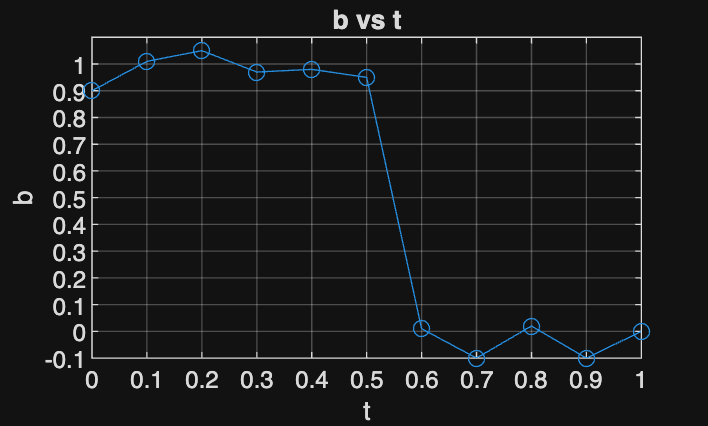

% Data vectors
t = 0.0:0.1:1.0;
b = [0.9 1.01 1.05 0.97 0.98 0.95 0.01 -0.1 0.02 -0.1 0.0];

% Create table
T = table(t(:), b(:), 'VariableNames', {'t','b'});

% Quick plot
figure
plot(T.t, T.b, '-o')
xlabel('t')
ylabel('b')
title('b vs t')
grid on

% Set axis limits
xlim([min(T.t) max(T.t)])
ylim([floor(min(T.b)*10)/10, ceil(max(T.b)*10)/10])  % round to nearest 0.1

% Force ticks every 0.1
xticks(min(T.t):0.1:max(T.t))
yticks(round( (min(T.b):0.1:max(T.b)) , 10)) % ensure floating-point spacing

            (b) Find the piecewise constant function which best fits the data by least squares, and plot it with the data set

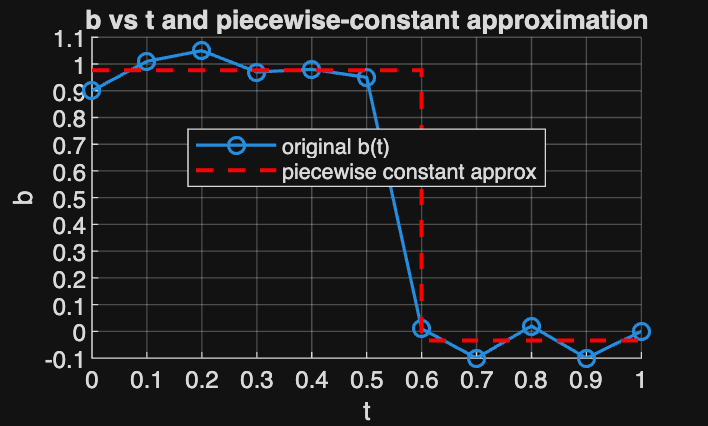

% Piecewise constant approximation
b_pw = zeros(size(t));
b_pw(t <= 0.55) = 0.9767;
b_pw(t >  0.55) = -0.034;

% Plot data and piecewise constant on the same axes
figure
hold on
plot(t, b, '-o', 'LineWidth', 1.2, 'DisplayName', 'original b(t)')
% Use stairs for piecewise-constant appearance
stairs(t, b_pw, 'r--', 'LineWidth', 1.5, 'DisplayName', 'piecewise constant approx')
hold off

xlabel('t')
ylabel('b')
title('b vs t and piecewise-constant approximation')
legend('Location','best')
grid on

% Force ticks every 0.1
xticks(min(t):0.1:max(t))
% choose y-limits padded to nearest 0.1 and set yticks every 0.1
ymin = floor(min([b b_pw])*10)/10;
ymax = ceil (max([b b_pw])*10)/10;
ylim([ymin ymax])
yticks(ymin:0.1:ymax)